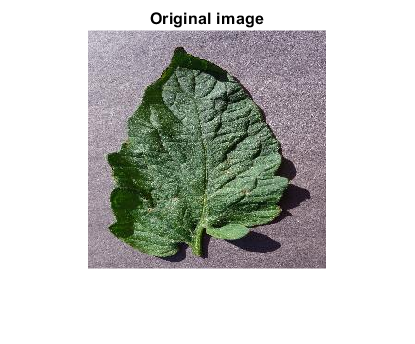

clear all
close all
clc
datacursormode on;
set(gca,'Color','white')
I = imread("Target_Spot_1.JPG");
imshow(I),title('Original image')

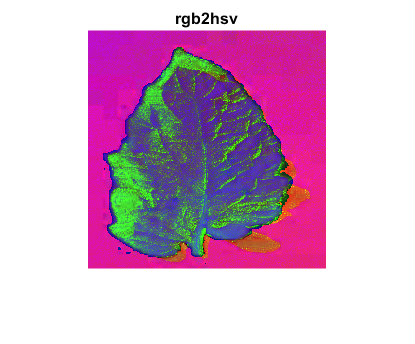

I_sRGB = rgb2hsv(I);
%I_sRGB_Plane1 = I_sRGB(:,:,1);
%I_sRGB_Plane2 = I_sRGB(:,:,2);
%I_sRGB_Plane3 = I_sRGB(:,:,3);
imshow(I_sRGB),title('rgb2hsv')

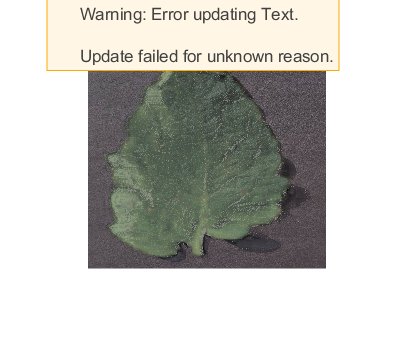


[h,s,v] = imsplit(I_sRGB);
B = imfuse(s,I,'blend','Scaling','joint');
imshow(B)

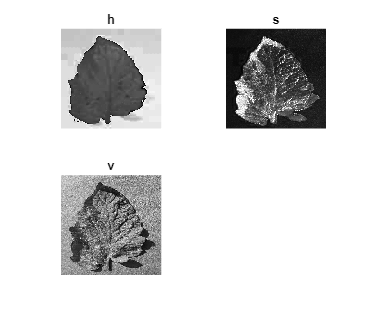

subplot(2,2,1),imshow(h,[]),title('h')
subplot(2,2,2),imshow(s,[]),title('s')
subplot(2,2,3),imshow(v,[]),title('v')

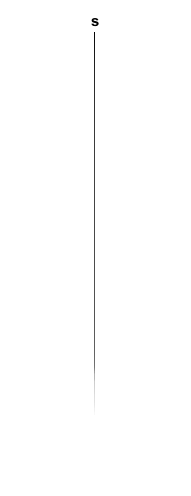

C = intersect(h,s);
figure(2),imshow(C),title('s')